# LMSフィルタ比較

## フィルタ長による比較

fleng     = 20;     %タップ数
fsize     = 5000;    %フレームサイズ

lengthF = 5;
lengthInit = 10;

ssize = 0.0001;

Ni = 200;
nlmst = zeros(Ni,1);
graphF = false;
mode = true; % true = white noise
              % false = pink noise



for i = 1:Ni
    
    fleng = lengthInit + i * lengthF;
    
    eval(['lmsfilt',num2str(i),' = dsp.LMSFilter(',...
        '''Length''',',fleng,','''Method''',',',...
        '''Normalized LMS''',',','''StepSize''',',','ssize',');']);
end

## ノイズ

Hp = dsp.ColoredNoise('Color','pink','SamplesPerFrame',fsize);
dp = Hp();

Hw = dsp.ColoredNoise('Color','white','SamplesPerFrame',fsize);
dw = Hw();

firfilt = dsp.FIRFilter('Numerator', fir1(10,[.5, .75]));

xp = firfilt(dp);
xw = firfilt(dw);

calcSsizeP = 2/sqrt(dp'*dp)

calcSsizeP = 0.0177

calcSsizeW = 2/sqrt(dw'*dw)

calcSsizeW = 0.0283


if graphF == true
    
    for i = 1:Ni
        eval(['TS',num2str(i),' = dsp.TimeScope(','''TimeSpan''',',1.1*fsize,',...
            '''TimeUnits''',',','''Seconds''',',','''YLimits''',...
            ',[-3 3],','''BufferLength''',',4*fsize,','''ShowLegend''',...
            ',true,','''ChannelNames''',', {','''Noisy signal''',',', '''err''','},',...
            '''Title''',',''',num2str(ssize(i)),''');']);
    end
    
end
TSe = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'LMS', 'NLMS', 'AP', 'RLS'},'Title','Err');

## ホワイトノイズ

if mode == true
    for i = 1:Ni
        tic;
        eval(['[~,e',num2str(i),'] = lmsfilt',num2str(i),'(dw,xw);']);
        nlmst(i) = toc;
        
        if graphF == true
            eval(['TS',num2str(i),'([xw,e',num2str(i),']);'])
        end
    end
end

## ピンクノイズ

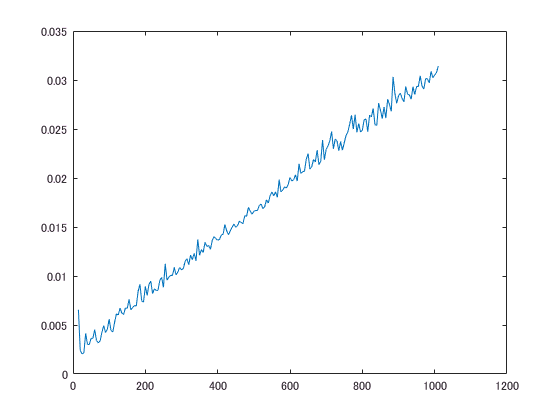

if mode == false
    for i = 1:Ni
        tic;
        eval(['[~,e',num2str(i),'] = lmsfilt',num2str(i),'(dp,xp);']);
        nlmst(i) = toc;
        
        if graphF == true
            eval(['TS',num2str(i),'([xp,e',num2str(i),']);'])
        end
    end
end
plot(lengthF+lengthInit:lengthF:fleng,nlmst);